# Lab 4 Data

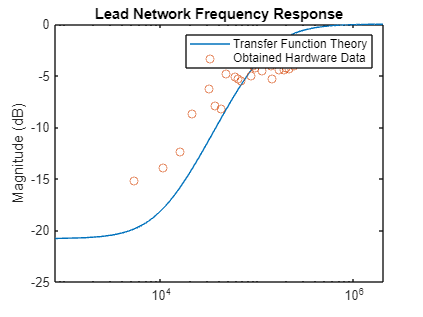

load handel.mat
sound(y)
% Part 1: Implies that fExp, AExp are imported from Excel
% Ensure that below are correct definitions for phase shift of exp data
fpExp = transpose([1022, 35186, 1211500]);
phExp = transpose([4.16, 54.72, 4.51]);
% TF and body plot for theoretical values
R1 = 1.5e3;
R2 = 150;
C = 10e-9;
ftheory = transpose(linspace(0,2000000, 2500));
% magnitude and phase for thang
        magnum = (j*2*pi.*ftheory + 1/(R1*C));
        magden = (j*2*pi.*ftheory + (R2+R1)/(R1*R2*C));
    Atheory = 20*log10(abs(magnum ./ magden));
    phasetheory = (180/pi)*(atan(2*pi*ftheory*R1*C) - atan((2*pi.*ftheory*R1*R2*C)/(R2+R1)));
% Cuttoff frequencies and critical frequencies for determining input
fp = (R2+R1)/(R1*R2*C*2*pi);
fz = 1/(R1*C*2*pi);
critical_freq = {fz/2, fz, fz*2, fp/2, fp, fp*2};
% Since Gain will be 0 at DC*n, if n=1 set at fz/2, DC set to 1/5 to ensure
% non-zero gain at the input frequencies that we wish to measure. 20%DC
% square wave at f0=fz/2 sent into network, gains at special frequencies
% recorded
figure;
%plot both theory magnitude response and experimental magnitude response
semilogx (ftheory, Atheory)
hold on;
semilogx (fExp, AExp, 'o')
title(" Lead Network Frequency Response ");
ylabel("Magnitude (dB)");
legend("Transfer Function Theory", "Obtained Hardware Data");

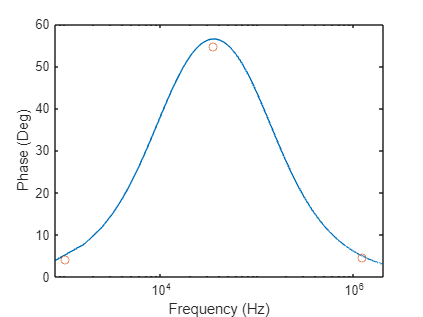

newplot;
figure;
%plot both theory phase response and experimental phase response
semilogx (ftheory, phasetheory)
hold on;
plot (fpExp, phExp, 'o')
xlabel("Frequency (Hz)");
ylabel("Phase (Deg)");

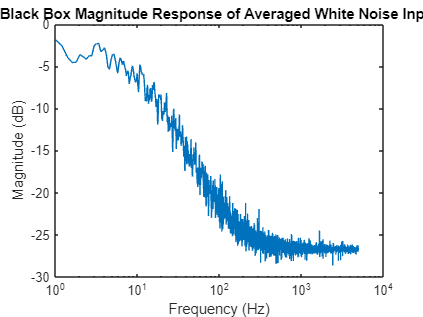


% Part 2: Implies that F, dB, and NoisedB are imported from Excel
newplot;
figure;
%plot noisy spectra
semilogx (F, NoiseDB);
title(" Black Box Magnitude Response of Averaged White Noise Input ");
ylabel("Magnitude (dB)");
xlabel("Frequency (Hz)");

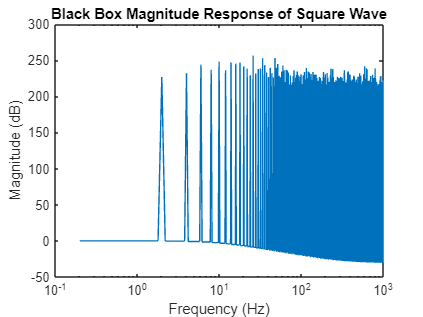

%plot smoother spectra
semilogx (Fsq, dB);
title(" Black Box Magnitude Response of Square Wave ");
ylabel("Magnitude (dB)");
xlabel("Frequency (Hz)");